# Atividade 13_04

Otávio Baziewicz Filho - 1942808

clc; clear; close all;

## Leitura e pseudocolorização de imagens térmicas

O arquivo frames.csv contém 20 frames (imagens) de um vídeo capturado com uma câmera térmica. Cada imagem tem altura de 240 pixels e largura de 320 pixels. Os valores dos pixels são as temperaturas em ˚C. No momento da aquisição das imagens, a câmera estava de cabeça para baixo.

Elabore um script para ler, pseudocolorir, e mostrar todas as 20 imagens. Faz parte da tarefa observar a estrutura das imagens no csv e deduzir como as 20 imagens estão organizadas, para que seja possível separar cada uma. Como as imagens estão de cabeça para baixo, corrija-as antes de mostrar.

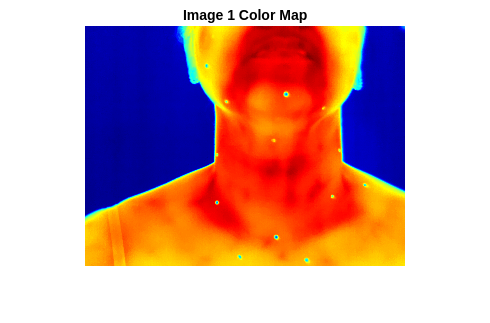

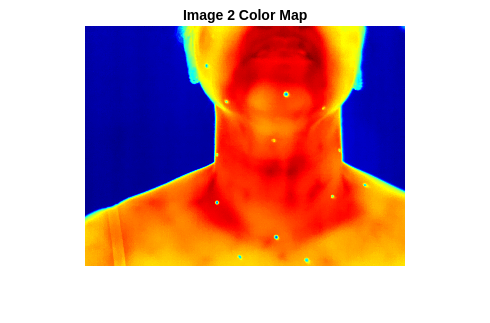

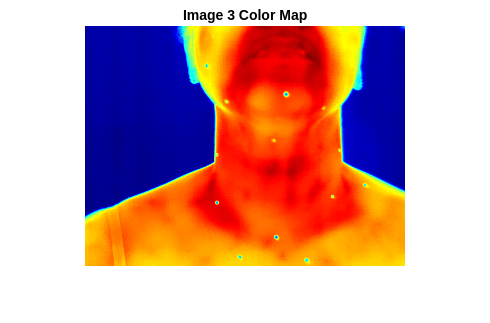

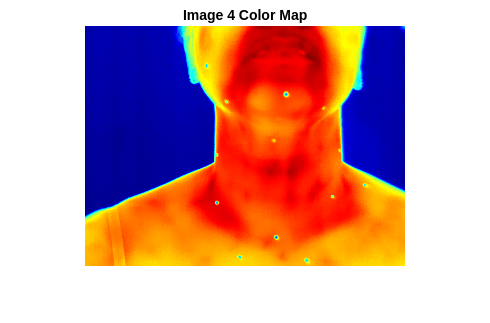

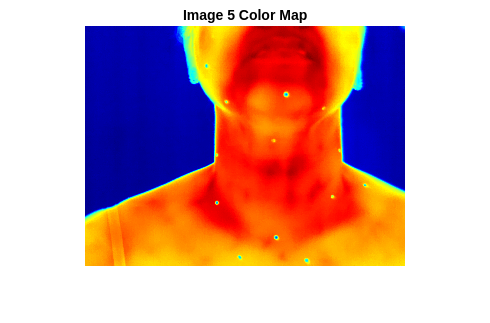

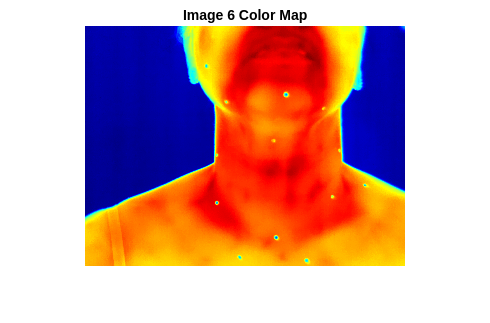

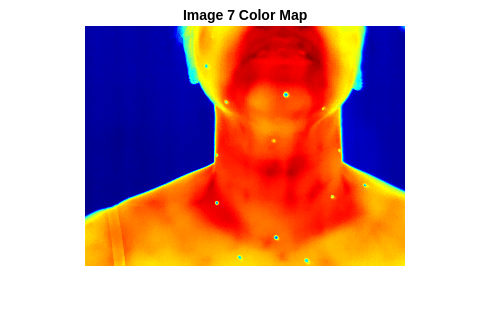

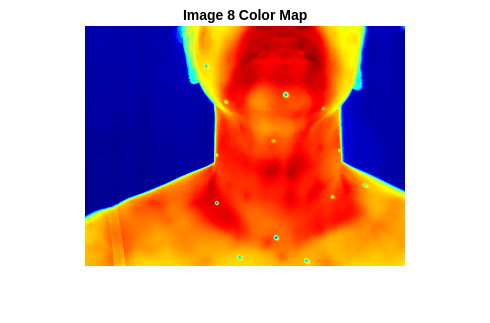

frames = readmatrix("frames.csv");

cm = colormap(jet(256));

for i = 1:20
    img = frames((i-1)*240+1:i*240,:);
    img = flip(img);
    img = mat2gray(img);
    img = uint8(img.*255);

    figure, imshow(img, cm), title("Image " + i + " Color Map")
end